clc, clear, close all

## Environment Setup

### Case

The thickness for all plates in the case is 25mm with the length, width, and height of the case being {280,210,300} mm. 

% case_length = 0.280; % mm
case_width = 0.420; % mm
% case_height = 0.600; % mm

#### Solid Front and Back Walls

solid_length = 0.610;
wall_thickness = 0.025;
solid_height = 0.600;

solid_back = collisionBox(solid_length, wall_thickness, solid_height);
solid_front = collisionBox(solid_length, wall_thickness, solid_height);

solid_front.Pose = trvec2tform([0.660/2, wall_thickness/2, wall_thickness + solid_height/2]);
solid_back.Pose = trvec2tform([0.660/2, case_width - wall_thickness/2, wall_thickness + solid_height/2]);

% show(solid_front)
% hold on
show(solid_back)
hold on

#### Front and Rear Walls



front1_height = 0.250-0.080;
front2_height = 0.230+ 0.160;
front3_height = 0.230+ 0.160;
front4_height = 0.650-0.23-0.25-0.08;
front5_height = 0.23-0.16;

% make front geometries
front1 = collisionBox(wall_thickness, 0.42, front1_height);
front2 = collisionBox(wall_thickness, 0.210-0.08, front2_height);
front3 = collisionBox(wall_thickness, 0.210-0.08, front3_height);
front4 = collisionBox(wall_thickness, 0.42, front4_height);
front5 = collisionBox(wall_thickness, 0.42-2*(0.210-0.08), front5_height);

% adjust front position
front1.Pose = trvec2tform([wall_thickness/2,0.42/2, front1_height/2]);
front2.Pose = trvec2tform([wall_thickness/2,(0.210-0.08)/2, front1_height + front2_height/2]);
front3.Pose = trvec2tform([wall_thickness/2,0.42-((0.210-0.08)/2), front1_height + front2_height/2]);
front4.Pose = trvec2tform([wall_thickness/2,0.42/2, front1_height + front2_height + front4_height/2]);
front5.Pose = trvec2tform([wall_thickness/2,0.42/2, front1_height + front2_height/2]);

% make rear geometries
rear1 = collisionBox(wall_thickness, 0.42, front1_height);
rear2 = collisionBox(wall_thickness, 0.210-0.08, front2_height);
rear3 = collisionBox(wall_thickness, 0.210-0.08, front3_height);
rear4 = collisionBox(wall_thickness, 0.42, front4_height);
rear5 = collisionBox(wall_thickness, 0.42-2*(0.210-0.08), front5_height);

% adjust rear position
rear1.Pose = trvec2tform([wall_thickness  + solid_length,0.42/2, front1_height/2]);
rear2.Pose = trvec2tform([wall_thickness + solid_length,(0.210-0.08)/2, front1_height + front2_height/2]);
rear3.Pose = trvec2tform([wall_thickness  + solid_length,0.42-((0.210-0.08)/2), front1_height + front2_height/2]);
rear4.Pose = trvec2tform([wall_thickness  + solid_length,0.42/2, front1_height + front2_height + front4_height/2]);
rear5.Pose = trvec2tform([wall_thickness + solid_length,0.42/2, front1_height + front2_height/2]);


show(front1)
xlim([-0.270 0.869])
ylim([-0.557 0.582])
zlim([-0.257 0.882])
view([-29.582 8.263])

% hold on
show(front2)
show(front3)
show(front4)
show(front5)
% hold off
% 
show(rear1)
% % hold on
show(rear2)
show(rear3)
show(rear4)
show(rear5)
% hold off

#### Solid Top and Bottom Walls

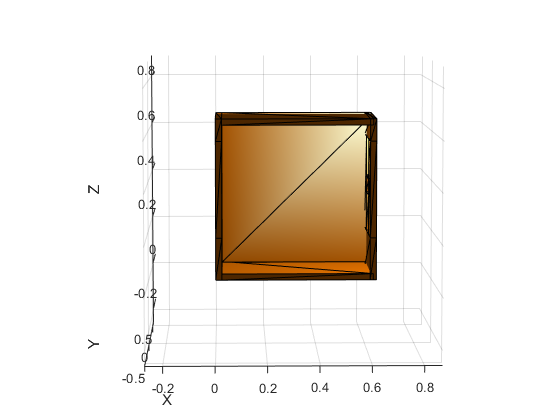

top = collisionBox(0.610, 0.420, 0.025);
bottom = collisionBox(0.610, 0.420, 0.025);

top.Pose = trvec2tform([0.330, 0.210, 0.650-(wall_thickness/2)]);
bottom.Pose = trvec2tform([0.330, 0.210, (wall_thickness/2)]);

show(top)
show(bottom)
hold off

### Countershaft

cs_1 = collisionCylinder(0.072, 0.660);
cs_2 = collisionCylinder(0.2, 0.05);
cs_3 = collisionCylinder(0.16, 0.05);
cs_4 = collisionCylinder(0.247, 0.05);
cs_5 = collisionCylinder(0.279, 0.05);
cs_6 = collisionCylinder(0.280, 0.05);



### Mainshaft

## Functions